clear;

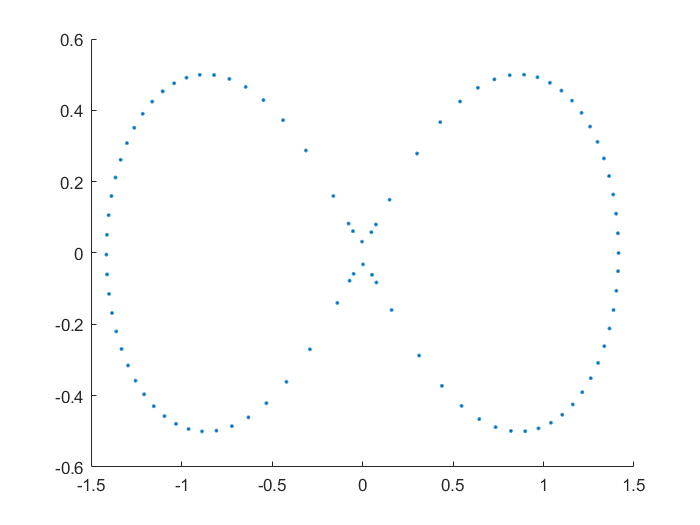

%Cassini Oval
count1 = 40;
count2 = 2;
a = 1;b = sqrt(1.001);
theta = [0         :(pi/2/count1): pi/2-0.71,...
        pi/2-0.7   :(pi/2/count2): pi/2+0.7,...
        pi/2+0.71  :(pi/2/count1): 3*pi/2-0.71,...
        3*pi/2-0.7 :(pi/2/count2): 3*pi/2+0.7,...
        3*pi/2+0.71:(pi/2/count1): 2*pi-0.01];
M = 2*a^2.*cos(2*theta)+2*sqrt(a^4.*(cos(2.*theta)).^2-a^4+b^4); 
Points = sqrt(M./2)'.*[cos(theta'),sin(theta')];

dM = -4*a^2.*sin(2*theta) - 4*(a^4).*sin(2.*theta).*cos(2*theta).*(b^4-a^4+a^4*(cos(2.*theta)).^2).^(-0.5);
dx = 0.25.*dM.*cos(theta).*(M./2).^(-0.5) - sqrt(M./2).*sin(theta);
dy = 0.25.*dM.*sin(theta).*(M./2).^(-0.5) + sqrt(M./2).*cos(theta);
dx = dx./sqrt(dx.^2+dy.^2);
dy = dy./sqrt(dx.^2+dy.^2);
Normals = [dy',-dx'];
for i=1:length(theta)
    Normals(i,:)=Normals(i,:)./sum(Normals(i,:).^2);
end
scatter(Points(:,1),Points(:,2),'.');

n = length(theta);

k = 6*ones(n,1);
s = -0.5;
% 生成kd树
kdtree = KDTreeSearcher(Points);
boxlength=norm(min(Points)-max(Points));
% 计算各点支撑半径
SupportSizes = zeros(n,1);

distlist=SupportSizes;
mindist=distlist;
for i=1:n
    [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
    SupportSizes(i) = max(dists);
    mindist(i)=(dists(2))/SupportSizes(i);
    distlist(i)=(sum(dists)/k(i))/SupportSizes(i);
end
maxSupportSize = max(SupportSizes);
% 生成局部坐标系，各点二次曲线
[Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);

for i=1:n
    Err(i)=sqrt(CalErr(Points(i,1),Points(i,2),Points,Bases,Hparas, ...
        kdtree,maxSupportSize,SupportSizes,SupportSizes(i)));
end


% 设置拟合系数
ApproxArgs = zeros(n,1);



meanerr=mean(Err);
maxerr=max(Err);
minerr=min(Err);
beta=1;
x=min(Points(:,1));xx=max(Points(:,1));
y=min(Points(:,2));yy=max(Points(:,2));
boxlength=sqrt((xx-x)^2+(yy-y)^2);
[d,dn]=CalSumd(Points,x,xx,y,yy);
d=d/dn;
c=2*d/boxlength;
x=zeros(n,1);

aa=zeros(n,1);
for i=1:n
    ApproxArgs(i) =c;
    [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
%     indices(1)=[];
%     maxerr=max(Err(indices));
%     minerr=min(Err(indices));
    if(Err(i)-meanerr>1e-7)
        x(i)=(Err(i)-meanerr)/(maxerr-minerr);
        ApproxArgs(i)=c/(1+x(i));
    elseif(Err(i)-meanerr<-1e-7)
        x(i)=(Err(i)-meanerr)/(maxerr-minerr);
        ApproxArgs(i)=c*(1-x(i));
    end


%     ApproxArgs(i) = c;
end



% ApproxArgs([24,70]) = 0;
% ApproxArgs([20,38,66,74]) = 0.5;
% ApproxArgs([68,69,70,71,72]) = 0;
% ApproxArgs([66,74,75]) = 1.5;
% 计算C值
C = zeros(n,1);
for i=1:n
    [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
    indices = indices{1};
    dists = dists{1};
    valsum = 0;
    rbfsum = 0;
    H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
    for j=1:length(indices)
        if dists(j)>=SupportSizes(indices(j))
            continue
        end
        %Wendland part
        value = rbf_wend(dists(j)/SupportSizes(indices(j)));
        %shepard part
%         value = rbf_shp(dists(j)/SupportSizes(indices(j)));
%         if(value==inf)
%             valsum=H(j);
%             rbfsum=1;
%             break;
%         end
%         Our method
        if dists(j)<1e-7 && ApproxArgs(indices(j))<1e-7 
            valsum = C(indices(j))+H(j);
            rbfsum = 1;
            break;
        end
        value = rbf(dists(j)/SupportSizes(indices(j)),ApproxArgs(indices(j)),s);
% %         
        valsum = valsum - H(j)*value;
        rbfsum = rbfsum + value;
    end
    C(i) = valsum/rbfsum;
end

% % 画隐曲线
 f = @(x,y)(CalRBFV(x,y,kdtree,Points, ...
     Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
% area = [-1.5,1.5,-0.7,0.7];
% fp = fimplicit(f, area);
% 
% hold on;
% scatter(Points(:,1),Points(:,2),'*');
% hold off;


%插值误差
F1=zeros(length(theta),1);
for j=1:length(theta)
    F1(j)=f(Points(j,1),Points(j,2));
end
Maxe1=max(abs(F1))

Maxe1 = 0.0016

Meane1=mean(abs(F1))

Meane1 = 2.5535e-04

%测试点误差
count1 = 4000;
count2 = 200;
a = 1;b = sqrt(1.001);
theta = [0         :(pi/2/count1): pi/2-0.71,...
     pi/2-0.7   :(pi/2/count2): pi/2+0.7,...
     pi/2+0.71  :(pi/2/count1): 3*pi/2-0.71,...
     3*pi/2-0.7 :(pi/2/count2): 3*pi/2+0.7,...
     3*pi/2+0.71:(pi/2/count1): 2*pi-0.01];
M = 2*a^2.*cos(2*theta)+2*sqrt(a^4.*(cos(2.*theta)).^2-a^4+b^4); 
respoints = sqrt(M./2)'.*[cos(theta'),sin(theta')];
F=zeros(length(theta),1);
for j=1:length(theta)
    F(j)=f(respoints(j,1),respoints(j,2));
end
Maxe2=max(abs(F))

Maxe2 = 0.0052

Meane2=mean(abs(F))

Meane2 = 3.5966e-04

% %绘制曲线
%  f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C));
% area = [-1,1,-1,1];
% fp = fimplicit(f, area);
% 
% hold on;
% scatter(respoints(:,1),respoints(:,2),'o');

% % %A series test
% count = 20:20:200;
% ttheta=cell(length(count),1);PPoints=ttheta;NNormals=PPoints;
% nn=PPoints;
% for i=1:length(count)
%     count1=count(i);
%     count2=count(i)/10;
%     a = 1;b = sqrt(1.001);
%     theta = [0         :(pi/2/count1): pi/2-0.71,...
%         pi/2-0.7   :(pi/2/count2): pi/2+0.7,...
%         pi/2+0.71  :(pi/2/count1): 3*pi/2-0.71,...
%         3*pi/2-0.7 :(pi/2/count2): 3*pi/2+0.7,...
%         3*pi/2+0.71:(pi/2/count1): 2*pi-0.01];
%     M = 2*a^2.*cos(2*theta)+2*sqrt(a^4.*(cos(2.*theta)).^2-a^4+b^4); 
%     Points = sqrt(M./2)'.*[cos(theta'),sin(theta')];
% 
%     dM = -4*a^2.*sin(2*theta) - 4*(a^4).*sin(2.*theta).*cos(2*theta).*(b^4-a^4+a^4*(cos(2.*theta)).^2).^(-0.5);
%     dx = 0.25.*dM.*cos(theta).*(M./2).^(-0.5) - sqrt(M./2).*sin(theta);
%     dy = 0.25.*dM.*sin(theta).*(M./2).^(-0.5) + sqrt(M./2).*cos(theta);
%     dx = dx./sqrt(dx.^2+dy.^2);
%     dy = dy./sqrt(dx.^2+dy.^2);
%     Normals = [dy',-dx'];
%     ttheta{i} = theta;
%     PPoints{i} = Points;
%     NNormals{i} = Normals;
%     nn{i} = length(ttheta{i});
% end
% 
% s=-0.5;
% 
% Maxtesterror=zeros(length(count),1);
% Meantesterror=zeros(length(count),1);
% 
% for j=1:length(count)
%    Points=PPoints{j};n=nn{j};
%     Normals=NNormals{j};
%     kdtree = KDTreeSearcher(Points);
%     k = 7*ones(n,1);
%     SupportSizes = zeros(n,1);
%     distlist=zeros(n,1);
%     mindist=distlist;
%     for i=1:n
%         [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
%         SupportSizes(i) = max(dists);
%         mindist(i)=dists(2);
%         distlist(i)=(sum(dists)/k(i))/SupportSizes(i);
%     end
%     maxSupportSize = max(SupportSizes);
%     ApproxArgs = zeros(n,1);
%     % 生成局部坐标系，各点二次曲线
%     [Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
%     meanerr=mean(Err);
%     var=sum((Err-meanerr).^2)/n;
%     meand=mean(distlist);
%     vard=sum((distlist-meand).^2)/n;
%     meanmd=mean(mindist);
%     varmd=sum((mindist-meanmd).^2)/n;
%     %%%计算对应的各个参数
%     c=1;
%     for i1=1:n
%         ApproxArgs(i1) = c;
%         if((mindist(i1)-meanmd)^2>3*varmd)
% %             i1=i
%             x=sqrt((mindist(i1)-meanmd)^2/(3*varmd));
%             if((mindist(i1)-meanmd)<0)
%                 %越稠密，越逼近
%                 ApproxArgs(i1)=c*(x);
%             else
%                  %越稀疏，越插值
%                 ApproxArgs(i1)=c*(1/x);
%             end
%         elseif((distlist(i1)-meand)^2>3*vard)
%             x=sqrt((distlist(i1)-meand)^2/(3*vard));
%             if((distlist(i1)-meand)>0)
%                 ApproxArgs(i1)=c/x;
%             else
%                 ApproxArgs(i1)=c*x;
%             end
%         elseif((Err(i1)-meanerr)^2>3*var)
%             x=sqrt((Err(i1)-meanerr)^2/(3*var));
%             if(Err(i)-meanerr>0)
%                 ApproxArgs(i1)=c/(x);
%             else
%                 ApproxArgs(i1)=c*x;
%             end
%         end
%     end
% 
%     %%%计算对应的各个参数
%     C = zeros(n,1);
%     for i=1:n
%         [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
%         indices = indices{1};
%         dists = dists{1};
%         valsum = 0;
%         rbfsum = 0;
%         H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
%         for j1=1:length(indices)
%             if dists(j1)>=SupportSizes(indices(j1))
%                 continue
%             end
%             %Wendland part
% %           value = rbf_wend(dists(j)/SupportSizes(indices(j)));
%             %shepard part
% %           value = rbf_shp(dists(j)/SupportSizes(indices(j)));
% %           if(value==inf)
% %               valsum=H(j);
% %               rbfsum=1;
% %               break;
% %           end
%             %Our method
%             if dists(j1)<1e-7 && ApproxArgs(indices(j1))<1e-7 
%                 valsum = C(indices(j1))+H(j1);
%                 rbfsum = 1;
%                 break;
%             end
%             value = rbf(dists(j1)/SupportSizes(indices(j1)),ApproxArgs(indices(j1)),s);
%         
%             valsum = valsum - H(j1)*value;
%             rbfsum = rbfsum + value;
%         end
%         C(i) = valsum/rbfsum;
%     end
%     f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
%     count1=4000;
%     count2=200;
%     a = 1;b = sqrt(1.001);
%     restheta = [0         :(pi/2/count1): pi/2-0.71,...
%         pi/2-0.7   :(pi/2/count2): pi/2+0.7,...
%         pi/2+0.71  :(pi/2/count1): 3*pi/2-0.71,...
%         3*pi/2-0.7 :(pi/2/count2): 3*pi/2+0.7,...
%         3*pi/2+0.71:(pi/2/count1): 2*pi-0.01];
%     M = 2*a^2.*cos(2*theta)+2*sqrt(a^4.*(cos(2.*theta)).^2-a^4+b^4); 
%     resPoints = sqrt(M./2)'.*[cos(theta'),sin(theta')];
%     F=zeros(length(restheta),1);
%     for i=1:length(restheta)
%         F(i)=f(respoints(i,1),respoints(i,2));
%     end
%     error2=abs(F);
%     Maxtesterror(j)=max(error2);
%     Meantesterror(j)=mean(error2);
% end

% Maxtesterror_W=zeros(length(count),1);
% Meantesterror_W=zeros(length(count),1);
% 
% for j=1:length(count)
%    Points=PPoints{j};n=nn{j};
%     Normals=NNormals{j};
%     kdtree = KDTreeSearcher(Points);
%     k = 7*ones(n,1);
%     for i=1:n
%         [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
%         SupportSizes(i) = max(dists);
%     end
%     maxSupportSize = max(SupportSizes);
%     % 生成局部坐标系，各点二次曲线
%     [Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
%     %%%计算对应的各个参数
%     C = zeros(n,1);
%     for i=1:n
%         [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
%         indices = indices{1};
%         dists = dists{1};
%         valsum = 0;
%         rbfsum = 0;
%         H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
%         for j1=1:length(indices)
%             if dists(j1)>=SupportSizes(indices(j1))
%                 continue
%             end
%             %Wendland part
%           value = rbf_wend(dists(j1)/SupportSizes(indices(j1)));
%             %shepard part
% %           value = rbf_shp(dists(j)/SupportSizes(indices(j)));
% %           if(value==inf)
% %               valsum=H(j);
% %               rbfsum=1;
% %               break;
% %           end
%             %Our method
% %             if dists(j1)<1e-7 && ApproxArgs(indices(j1))<1e-7 
% %                 valsum = C(indices(j1))+H(j1);
% %                 rbfsum = 1;
% %                 break;
% %             end
% %             value = rbf(dists(j1)/SupportSizes(indices(j1)),ApproxArgs(indices(j1)),s);
% %         
%             valsum = valsum - H(j1)*value;
%             rbfsum = rbfsum + value;
%         end
%         C(i) = valsum/rbfsum;
%     end
%     f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,2));
%     count1=4000;
%     count2=200;
%     a = 1;b = sqrt(1.001);
%     restheta = [0         :(pi/2/count1): pi/2-0.71,...
%         pi/2-0.7   :(pi/2/count2): pi/2+0.7,...
%         pi/2+0.71  :(pi/2/count1): 3*pi/2-0.71,...
%         3*pi/2-0.7 :(pi/2/count2): 3*pi/2+0.7,...
%         3*pi/2+0.71:(pi/2/count1): 2*pi-0.01];
%     M = 2*a^2.*cos(2*theta)+2*sqrt(a^4.*(cos(2.*theta)).^2-a^4+b^4); 
%     resPoints = sqrt(M./2)'.*[cos(theta'),sin(theta')];
%     F=zeros(length(restheta),1);
%     for i=1:length(restheta)
%         F(i)=f(respoints(i,1),respoints(i,2));
%     end
%     error2=abs(F);
%     Maxtesterror_W(j)=max(error2);
%     Meantesterror_W(j)=mean(error2);
% end

% % figure;
% % plot(count,-log10(Maxtesterror),'-o',count,-log10(Meantesterror), '*-','linewidth', 1);
% % hold on
% % plot(count,-log10(Maxtesterror_W),'-o',count,-log10(Meantesterror_W), '*-','linewidth', 1);
% % legend('Max error I','Mean error I','Max error II','Mean error II','Location','Northwest')
% % hold off;

%A series test
alpha=0:0.05:2;
count1 = 40;
count2 = 2;
a = 1;b = sqrt(1.001);
theta = [0         :(pi/2/count1): pi/2-0.71,...
        pi/2-0.7   :(pi/2/count2): pi/2+0.7,...
        pi/2+0.71  :(pi/2/count1): 3*pi/2-0.71,...
        3*pi/2-0.7 :(pi/2/count2): 3*pi/2+0.7,...
        3*pi/2+0.71:(pi/2/count1): 2*pi-0.01];
M = 2*a^2.*cos(2*theta)+2*sqrt(a^4.*(cos(2.*theta)).^2-a^4+b^4); 
Points = sqrt(M./2)'.*[cos(theta'),sin(theta')];

dM = -4*a^2.*sin(2*theta) - 4*(a^4).*sin(2.*theta).*cos(2*theta).*(b^4-a^4+a^4*(cos(2.*theta)).^2).^(-0.5);
dx = 0.25.*dM.*cos(theta).*(M./2).^(-0.5) - sqrt(M./2).*sin(theta);
dy = 0.25.*dM.*sin(theta).*(M./2).^(-0.5) + sqrt(M./2).*cos(theta);
dx = dx./sqrt(dx.^2+dy.^2);
dy = dy./sqrt(dx.^2+dy.^2);
Normals = [dy',-dx'];
n = length(theta);


s=-0.5;

Maxtesterror=zeros(length(alpha),1);
Meantesterror=zeros(length(alpha),1);
MaxIerror=zeros(length(a),1);
MeanIerror=zeros(length(a),1);


for j=1:length(alpha)
    kdtree = KDTreeSearcher(Points);
    k = 6*ones(n,1);
    SupportSizes = zeros(n,1);
    distlist=zeros(n,1);
    mindist=distlist;
    for i=1:n
        [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
        SupportSizes(i) = max(dists);
        mindist(i)=dists(2);
        distlist(i)=(sum(dists)/k(i))/SupportSizes(i);
    end
    maxSupportSize = max(SupportSizes);
    ApproxArgs = zeros(n,1);
    % 生成局部坐标系，各点二次曲线
    [Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
    meanerr=mean(Err);
    var=sum((Err-meanerr).^2)/n;
    meand=mean(distlist);
    vard=sum((distlist-meand).^2)/n;
    meanmd=mean(mindist);
    varmd=sum((mindist-meanmd).^2)/n;
    %%%计算对应的各个参数
    c=alpha(j);
    for i1=1:n
        ApproxArgs(i1) = c;
        if((mindist(i1)-meanmd)^2>3*varmd)
%             i1=i
            x=sqrt((mindist(i1)-meanmd)^2/(3*varmd));
            if((mindist(i1)-meanmd)<0)
                %越稠密，越逼近
                ApproxArgs(i1)=c*(x);
            else
                 %越稀疏，越插值
                ApproxArgs(i1)=c*(1/x);
            end
        elseif((distlist(i1)-meand)^2>3*vard)
            x=sqrt((distlist(i1)-meand)^2/(3*vard));
            if((distlist(i1)-meand)>0)
                ApproxArgs(i1)=c/x;
            else
                ApproxArgs(i1)=c*x;
            end
        elseif((Err(i1)-meanerr)^2>3*var)
            x=sqrt((Err(i1)-meanerr)^2/(3*var));
            if(Err(i)-meanerr>0)
                ApproxArgs(i1)=c/(x);
            else
                ApproxArgs(i1)=c*x;
            end
        end
    end
    %%%计算对应的各个参数
    C = zeros(n,1);
    for i=1:n
        [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
        indices = indices{1};
        dists = dists{1};
        valsum = 0;
        rbfsum = 0;
        H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
        for j1=1:length(indices)
            if dists(j1)>=SupportSizes(indices(j1))
                continue
            end
            %Wendland part
%           value = rbf_wend(dists(j)/SupportSizes(indices(j)));
            %shepard part
%           value = rbf_shp(dists(j)/SupportSizes(indices(j)));
%           if(value==inf)
%               valsum=H(j);
%               rbfsum=1;
%               break;
%           end
            %Our method
            if dists(j1)<1e-7 && ApproxArgs(indices(j1))<1e-7 
                valsum = C(indices(j1))+H(j1);
                rbfsum = 1;
                break;
            end
            value = rbf(dists(j1)/SupportSizes(indices(j1)),ApproxArgs(indices(j1)),s);
        
            valsum = valsum - H(j1)*value;
            rbfsum = rbfsum + value;
        end
        C(i) = valsum/rbfsum;
    end
    f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
    F=zeros(length(theta),1);
    for i=1:length(theta)
        F(i)=f(Points(i,1),Points(i,2));
    end
    error1=abs(F);
    count1=4000;
    count2=200;
    a = 1;b = sqrt(1.001);
    restheta = [0         :(pi/2/count1): pi/2-0.71,...
        pi/2-0.7   :(pi/2/count2): pi/2+0.7,...
        pi/2+0.71  :(pi/2/count1): 3*pi/2-0.71,...
        3*pi/2-0.7 :(pi/2/count2): 3*pi/2+0.7,...
        3*pi/2+0.71:(pi/2/count1): 2*pi-0.01];
    M = 2*a^2.*cos(2*theta)+2*sqrt(a^4.*(cos(2.*theta)).^2-a^4+b^4); 
    resPoints = sqrt(M./2)'.*[cos(theta'),sin(theta')];
    F=zeros(length(restheta),1);
    for i=1:length(restheta)
        F(i)=f(respoints(i,1),respoints(i,2));
    end
    error2=abs(F);
    Maxtesterror(j)=log10(max(error2));
    Meantesterror(j)=log10(mean(error2));
    MaxIerror(j)=log10(max(error1));
    MeanIerror(j)=log10(mean(error1));
end

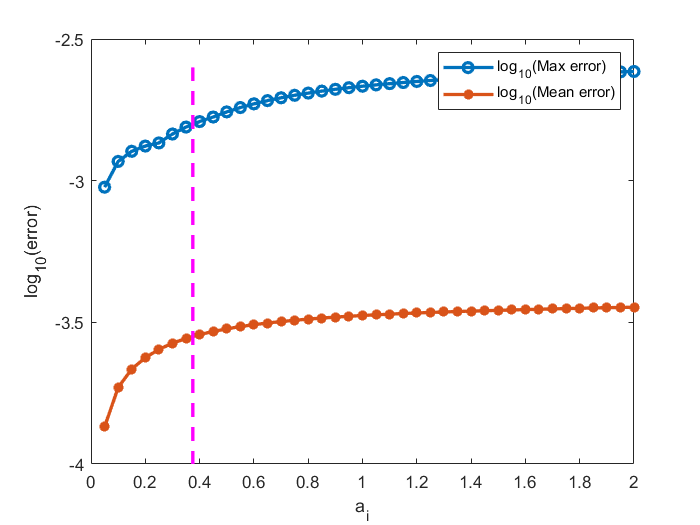

plot(alpha,MaxIerror,'-o',alpha,MeanIerror, '-*','linewidth', 2);
hold on
plot([0.375,0.375],ylim,'m--','linewidth', 2);
xlabel('a_i')
ylabel('log_{10}(error)')
legend('log_{10}(Max error)','log_{10}(Mean error)')
hold off

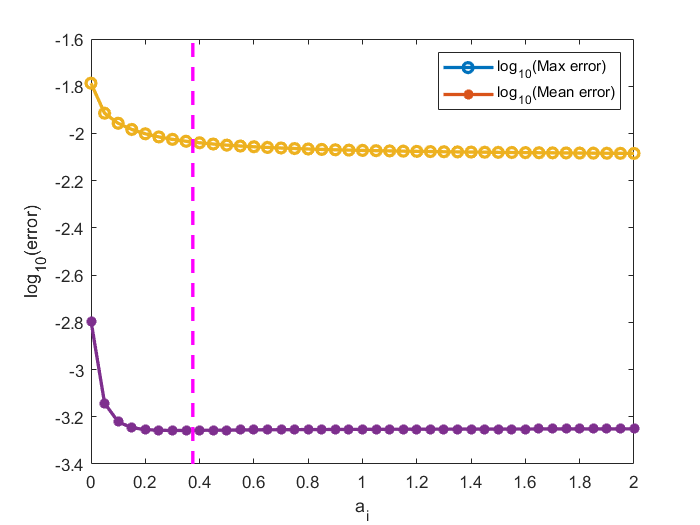

plot(alpha,Maxtesterror,'-o',alpha,Meantesterror, '-*','linewidth', 2);
hold on
plot([0.375,0.375],ylim,'m--','linewidth', 2);
xlabel('a_i')
ylabel('log_{10}(error)')
legend('log_{10}(Max error)','log_{10}(Mean error)')
hold off